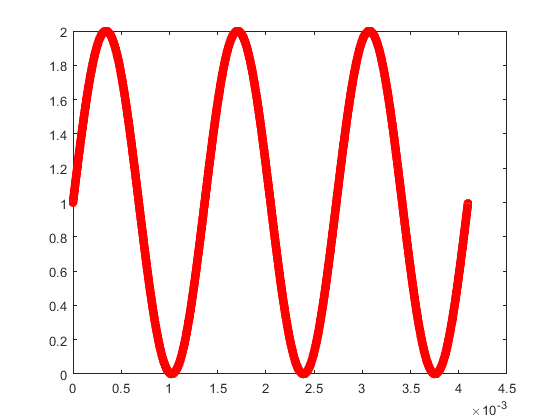

clc;
clear;
N = 3;
NFFT = 2^12;
fs = 1e6;
dt = 1/fs;
F = N*fs/NFFT;
t = [0 : dt : dt*(NFFT-1)];
data = 1+sin(2*pi*F*t);
plot(t, data, '-or');

quant = max(data)/(2^8-1);
data_dig = round(data/quant);

b0 = 1; b1 = 2; b2 = 4; b3 = 8; b4 = 16; b5 = 32; b6 = 64; b7 = 128;
d0 = []; d1 = []; d2 = []; d3 = []; d4 = []; d5 = []; d6 = []; d7 = [];
d0_com = []; d1_com = []; d2_com = []; d3_com = []; d4_com = []; d5_com = []; d6_com = []; d7_com = [];

t_tran = dt/1000;
for(t_itr = [0 : dt : dt*(NFFT-1)])
    i = round(t_itr/dt)+1;
    if(i > 1)
        d0 = [d0; t_itr-t_tran bitand(data_dig(i-1),b0)/b0];
        d1 = [d1; t_itr-t_tran bitand(data_dig(i-1),b1)/b1];
        d2 = [d2; t_itr-t_tran bitand(data_dig(i-1),b2)/b2];
        d3 = [d3; t_itr-t_tran bitand(data_dig(i-1),b3)/b3];
        d4 = [d4; t_itr-t_tran bitand(data_dig(i-1),b4)/b4];
        d5 = [d5; t_itr-t_tran bitand(data_dig(i-1),b5)/b5];
        d6 = [d6; t_itr-t_tran bitand(data_dig(i-1),b6)/b6];
        d7 = [d7; t_itr-t_tran bitand(data_dig(i-1),b7)/b7];
        d0_com = [d0_com; t_itr-t_tran ~(bitand(data_dig(i-1),b0)/b0)];
        d1_com = [d1_com; t_itr-t_tran ~(bitand(data_dig(i-1),b1)/b1)];
        d2_com = [d2_com; t_itr-t_tran ~(bitand(data_dig(i-1),b2)/b2)];
        d3_com = [d3_com; t_itr-t_tran ~(bitand(data_dig(i-1),b3)/b3)];
        d4_com = [d4_com; t_itr-t_tran ~(bitand(data_dig(i-1),b4)/b4)];
        d5_com = [d5_com; t_itr-t_tran ~(bitand(data_dig(i-1),b5)/b5)];
        d6_com = [d6_com; t_itr-t_tran ~(bitand(data_dig(i-1),b6)/b6)];
        d7_com = [d7_com; t_itr-t_tran ~(bitand(data_dig(i-1),b7)/b7)];
    end
    d0 = [d0; t_itr bitand(data_dig(i),b0)/b0];
    d1 = [d1; t_itr bitand(data_dig(i),b1)/b1]; 
    d2 = [d2; t_itr bitand(data_dig(i),b2)/b2]; 
    d3 = [d3; t_itr bitand(data_dig(i),b3)/b3];
    d4 = [d4; t_itr bitand(data_dig(i),b4)/b4];
    d5 = [d5; t_itr bitand(data_dig(i),b5)/b5];
    d6 = [d6; t_itr bitand(data_dig(i),b6)/b6];
    d7 = [d7; t_itr bitand(data_dig(i),b7)/b7];
    d0_com = [d0_com; t_itr ~(bitand(data_dig(i),b0)/b0)];
    d1_com = [d1_com; t_itr ~(bitand(data_dig(i),b1)/b1)];
    d2_com = [d2_com; t_itr ~(bitand(data_dig(i),b2)/b2)];
    d3_com = [d3_com; t_itr ~(bitand(data_dig(i),b3)/b3)];
    d4_com = [d4_com; t_itr ~(bitand(data_dig(i),b4)/b4)];
    d5_com = [d5_com; t_itr ~(bitand(data_dig(i),b5)/b5)];
    d6_com = [d6_com; t_itr ~(bitand(data_dig(i),b6)/b6)];
    d7_com = [d7_com; t_itr ~(bitand(data_dig(i),b7)/b7)];
end

save("sin_D0.txt", "d0", "-ascii");
save("sin_D1.txt", "d1", "-ascii");
save("sin_D2.txt", "d2", "-ascii");
save("sin_D3.txt", "d3", "-ascii");
save("sin_D4.txt", "d4", "-ascii");
save("sin_D5.txt", "d5", "-ascii");
save("sin_D6.txt", "d6", "-ascii");
save("sin_D7.txt", "d7", "-ascii");
save("sin_D0_com.txt", "d0_com", "-ascii");
save("sin_D1_com.txt", "d1_com", "-ascii");
save("sin_D2_com.txt", "d2_com", "-ascii");
save("sin_D3_com.txt", "d3_com", "-ascii");
save("sin_D4_com.txt", "d4_com", "-ascii");
save("sin_D5_com.txt", "d5_com", "-ascii");
save("sin_D6_com.txt", "d6_com", "-ascii");
save("sin_D7_com.txt", "d7_com", "-ascii");
